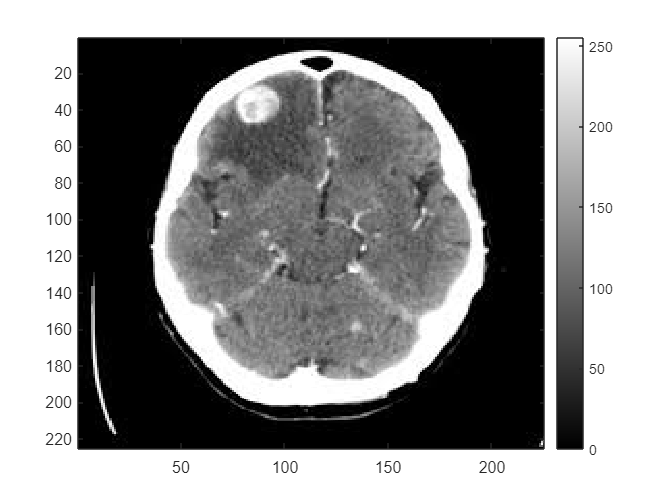

%Problem 3: Load the CT scan (1 slice of a 3D volume) into Matlab. Segment the tumor (hyperintensity in upper left corner) and calculate its area as a fraction of the total brain area. Hint: Intensity thresholding might be not enough to differentiate the tumor from the bone, so you will need to come up with an additional criterion. All steps should be defined computationally i.e. no drawing of masks in an image processing program.
%(Note: This is a hard problem and we want mostly to get you to think about ideas and strategies how to address it. So, no worries if you cannot fully solve it but we would like to see some ideas on how to make progress.)

clear all
close all
I = imread('CT.jpg');
I = rgb2gray(I);
figure; imagesc(I), colorbar, colormap(gray)

% Finding all circles in the image
[centre, radius] = imfindcircles(I,[1 100000])

centre =     8.9993  183.0088
   41.2917   97.9167
  190.4128   96.1998
   13.0223  201.6099
   86.0314   40.0014
  193.4140  131.8595
  110.1671  183.2264
  135.2262  102.8533
  117.2677   13.8572


radius =     1.4692
    3.6249
    3.3570
    1.4695
   10.4319
    3.0018
    5.9243
    2.1283
    8.2598



% After Iterating through the circles found in the previous function to see that
% the circle corresponding to index 5 is the tumor 

centre_tumor = centre(5,:)

centre_tumor =    86.0314   40.0014


radius_tumor = radius(5)

radius_tumor = 10.4319

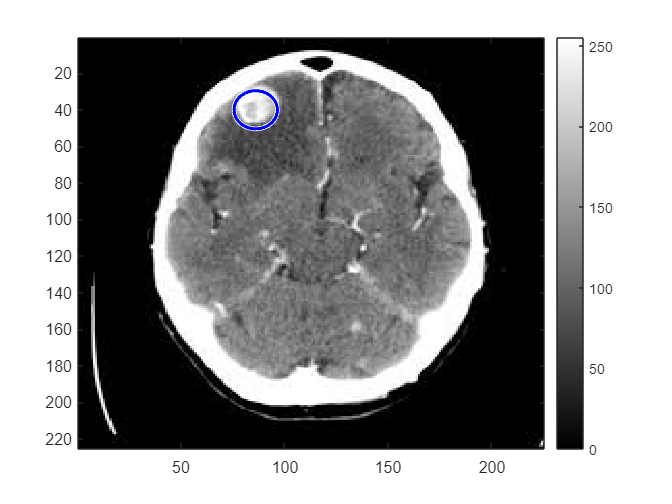


viscircles(centre_tumor,radius_tumor,'Color','b'); 

%Area within the circle 

area_tumor = (radius_tumor)^2 * pi;
area_tumor = ceil(area_tumor)

area_tumor = 342

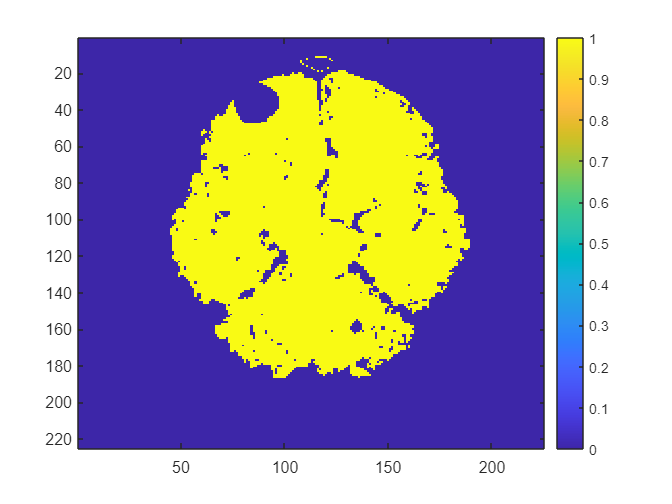

% Segmenting the brain into skull and tissue by trial and error

skull = I>240;
brain = I>50 & I <150;

skull_filled = imfill(skull,'holes');
brain2 = brain+skull_filled;

brain3 = brain2 >1.5;
figure; imagesc(brain3); colorbar

% Total brain Area

brainA = 16255


brainA = sum(brain3(:) == 1)

% Tumor area percent from the total brains

tumor_percent = 100*area_tumor/(brainA+area_tumor)

tumor_percent = 2.0606